# This example illustrates how the Toolkit could be used to develop a hydrant rating curve used in fire flow studies.

This curve shows the amount of flow available at a node in the system as a function of pressure. The curve is generated by running a number of steady state hydraulic analyses with the node of interest subjected to a different demand in each analysis. For this example we assume that the ID label of the node of interest is MyNode and that N different demand levels stored in the array D need to be examined. The corresponding pressures will be stored in P. To keep the code more readable, no error checking is made on the results returned from the Toolkit function calls.

## [https://github.com/OpenWaterAnalytics/EPANET/wiki/Example-2](https://github.com/OpenWaterAnalytics/EPANET/wiki/Example-2)

## Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.
EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


ans = int32
   11


EPANET Class is unloaded


## Load a network

d = epanet('Net1.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


## Select node of interest

nodeID = '32';

## Select number of iterations

r = 1:0.5:10;

d.openHydraulicAnalysis;

nodeIndex = d.getNodeIndex(nodeID);

B = d.getNodeBaseDemands{1}(nodeIndex); % {1} beacause its category
D = B.*r;

N = length(D);
for i = 1:N
    d.setNodeBaseDemands(nodeIndex, D(i));
    d.initializeHydraulicAnalysis;
    d.runHydraulicAnalysis;
    P(i) = d.getNodePressure(nodeIndex);
end
P

P =           110.790184020996          109.077308654785          106.906730651855          104.300132751465          101.272148132324          97.8340530395508          93.9950790405273          89.7630081176758          85.1445693969727          80.1457138061523          74.7717514038086          69.0275039672852          62.9173965454102          56.4455604553223          49.6158447265625          42.4293632507324          34.8847045898438           26.985179901123          18.7340850830078



d.closeHydraulicAnalysis;

## Unload library

d.unload

EPANET Class is unloaded


## Plots

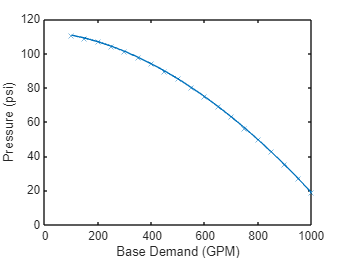

plot(D,P,'-x')  
xlabel(['Base Demand (', d.NodeDemandUnits, ')'])
ylabel(['Pressure (', d.NodePressureUnits,')'])